# Detect Heartbeats and ECG Features Using Bandpass Filtering and Peak Detection

This example demonstrates how to detect R-peaks and estimate heart rate from an Electrocardiogram (ECG) signal using basic signal processing techniques in MATLAB. The workflow includes acquiring ECG data, filtering the signal to remove noise, and identifying heartbeats using peak detection.

The data used in this example can be acquired from a wearable device such as a BITalino board and should be provided in a supported file format described in the Data description section. While this example does not include code for acquiring ECG data directly from [BITalino](https://www.pluxbiosignals.com/collections/bitalino?srsltid=AfmBOorALQY6SNKViG8JypRobeGXwezf108ouDzG5tW3Qt316vIDQaYb), you can refer to the [Getting Started with BITalino guide](https://www.mathworks.com/matlabcentral/fileexchange/136004-matlab-support-for-bitalino-biosignal-devices) for instructions on data acquisition and device setup.

This example does require an additional Add-On beyond MATLAB, this being the Signal Processing Toolbox and is intended to work with raw ECG data for straightforward analysis and visualization.

The figure below demonstrates the typical output of this ECG signal processing function. It includes the raw ECG signal, the filtered signal with detected R-peaks, and the resulting heart rate variability (HRV) over time. 

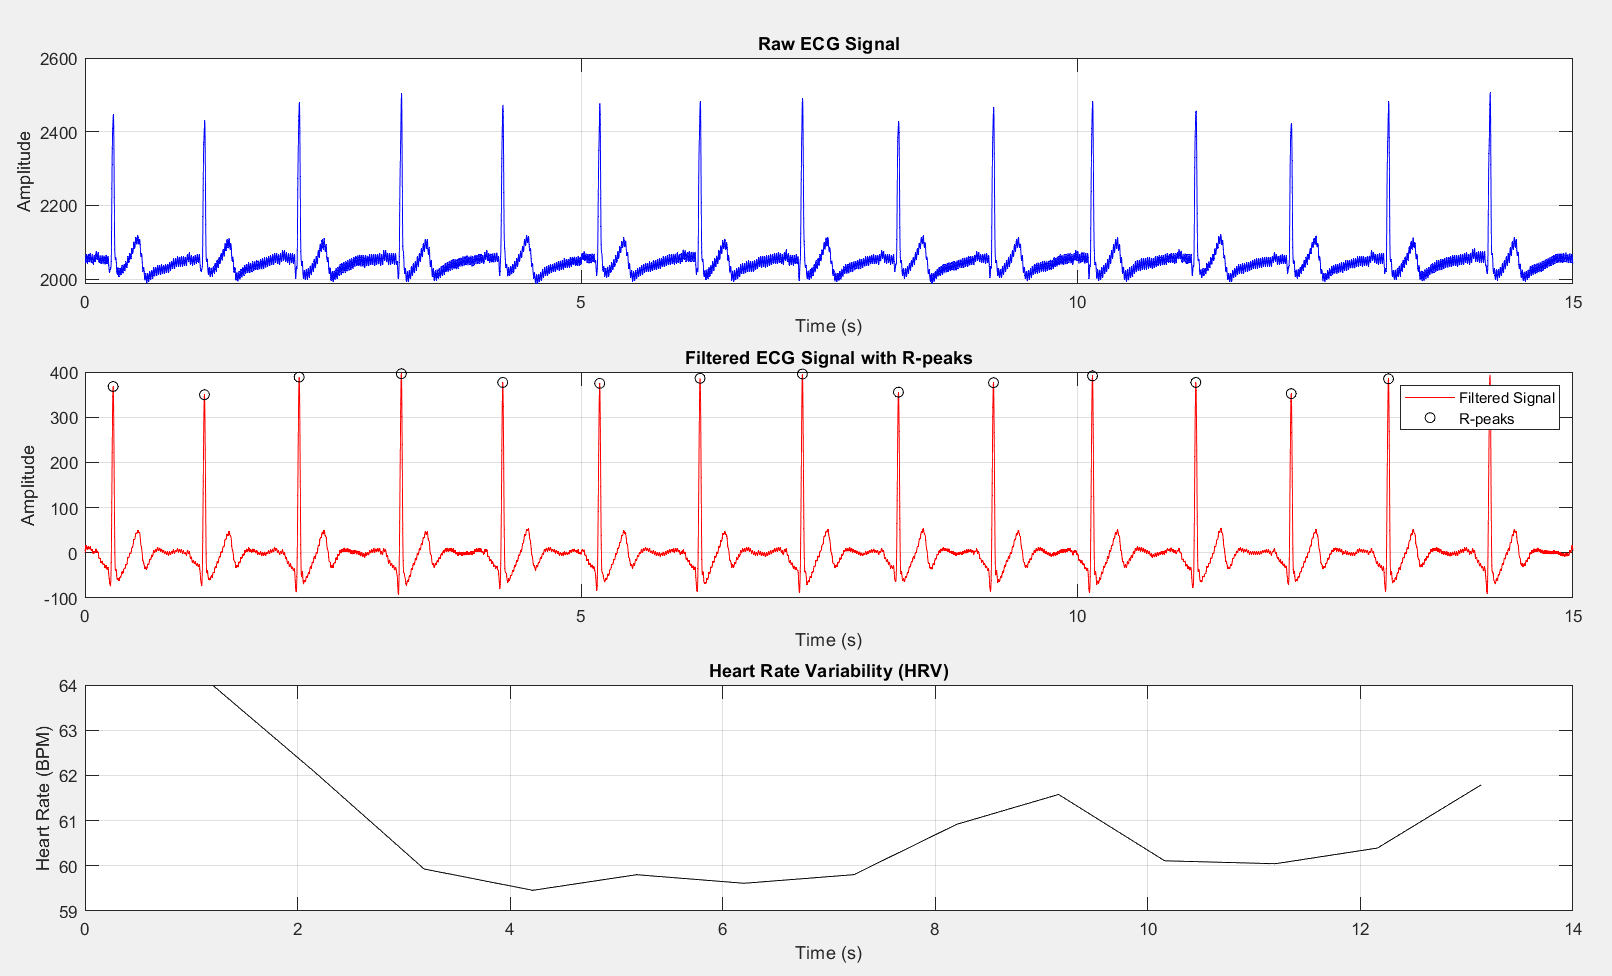

## Data Description

This example works with ECG recordings stored as plain text, csv or data files containing a single column of sampled voltage values. The signal represents a single lead ECG waveform, such as those captured using wearable sensors like the BITalino board or similar acquisition systems.

It is also possible to use more complex datafiles using the *readtable* function to extract the column of interest. The sample data used in this example can be recorded by the user or obtained from publicly available datasets, as long as it is formatted accordingly.

## Download Data

The first step is to acquire an ECG recording to use as input for the analysis. As mentioned before, this example supports data collected from a BITalino device or publicly available ECG datasets such as those provided by [PhysioNet](https://physionet.org/).

This example uses a collection of [datasets](https://github.com/mathworks/physionet_ECG_data/). Being these datasets from[ MIT-BIH Arrhythmia Database](https://www.physionet.org/content/mitdb/1.0.0/), [MIT-BIH Normal Sinus Rhythm Database](https://www.physionet.org/content/nsrdb/1.0.0/) and [BIDMC Congestive Heart Failure Database](https://www.physionet.org/content/chfdb/1.0.0/).

The filename and sampling rate can be specified when running the example. If not specified, the sampling rate defaults to 128 Hz since this is the sampling rate of the example shown.

If you download data from PhysioNet, follow the source’s guidelines for data citation and usage. Some datasets may include additional metadata or annotations; however, for this example, only the raw ECG signal is required. Because of that, to use those data *readtable* has to be used selecting the column of interest.

## Load File 

If choosen a sample from PhysioNet you can unzip and load them using the following commands.

% Download and unzip the example Data
if ~exist("ECGData.mat", 'file')
    url = 'https://github.com/mathworks/physionet_ECG_data/archive/refs/heads/main.zip';
    unzip(url);
    unzip("physionet_ECG_data-main\ECGData.zip");
end
load("ECGData.mat")

Each ECG time series from this example has a total duration of 512 seconds.The `ECGData` is a structure array with two fields: `Data` and `Labels`. `Data` is a 162-by-65536 matrix where there are 162 rows, each row is a different patient data and the 65536 lines is the ecg voltage in time aquired, each of these ECG recordings is sampled at 128 Hz. `Labels` is a 162-by-1 cell array of diagnostic labels, one for each row of `Data`. The three diagnostic categories are: `'ARR'` (arrhythmia), `'CHF'` (congestive heart failure), and `'NSR'` (normal sinus rhythm).

## Plot the Raw ECG, Filtered ECG and heart rate variability

For the data from the example given,  you can select any of the 162 patients from ECGData by simply use any number from 1 to 162 bellow. The sampling rate for the example given is 128 Hz.

It is to note that most BITalino use a sampling rate of 1000Hz and using other data than the example given you have to adapt the sampling rate acordingly.

sample=ECGData.Data(110,:);

### Raw ECG Data

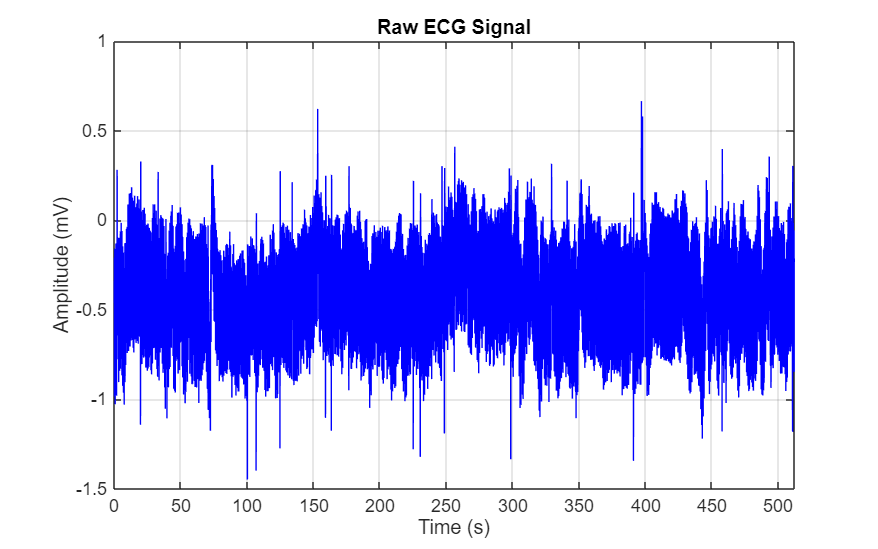

% Defining the Variables
samplingRate = 128;
signal = sample;
signalLength = length(signal);
ts = (0:signalLength-1)' / samplingRate;
titleFontSize = 16;
labelFontSize = 14;
legendFontSize = 12;
% Plot the raw ECG Signal
figure('Units','Normalized','OuterPosition',[0 0 1 1]);
plot(ts, signal, 'b');
title('Raw ECG Signal','FontSize',titleFontSize);
xlabel('Time (s)','FontSize',labelFontSize);
ylabel('Amplitude (mV)','FontSize',labelFontSize);
xlim([0 max(ts)]);
grid on;
set(gca,'FontSize',legendFontSize);

### Filtered Signal with R-peaks

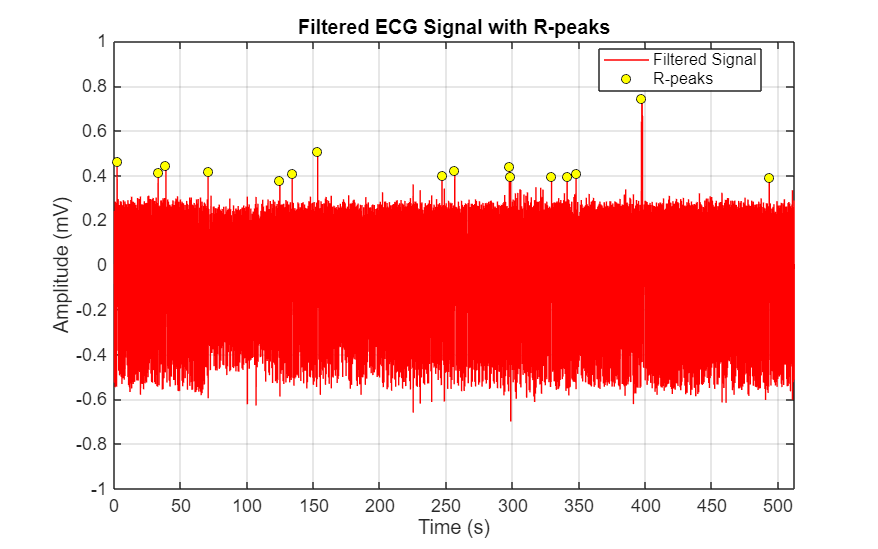

% Preprocess the ECG signal
smoothed_signal = smoothdata(signal,'movmean',5);
[b,a] = butter(4,[3, 45] / (samplingRate / 2),'bandpass');
filtered = filtfilt(b,a,signal);

% Detect the R-peaks
[pks,rpeaks] = findpeaks(filtered,'MinPeakHeight',0.5 * max(filtered), ...
'MinPeakDistance',0.6 * samplingRate);

% Plot the filtered ECG Signal
figure('Units','Normalized','OuterPosition',[0 0 1 1]);
plot(ts,filtered,'r');
hold on;
plot(ts(rpeaks),filtered(rpeaks),'o','MarkerFaceColor','y','MarkerEdgeColor','k');
title('Filtered ECG Signal with R-peaks','FontSize',16);
xlabel('Time (s)','FontSize',14);
ylabel('Amplitude (mV)','FontSize',14);

% Set x-axis limits to the duration of the signal
xlim([0 max(ts)]);

% Set y-axis limits for better visibility
ylim([-1 1]);
legend('Filtered Signal','R-peaks','Location','best');
grid on;
set(gca,'FontSize',12);

### Hear rate variability

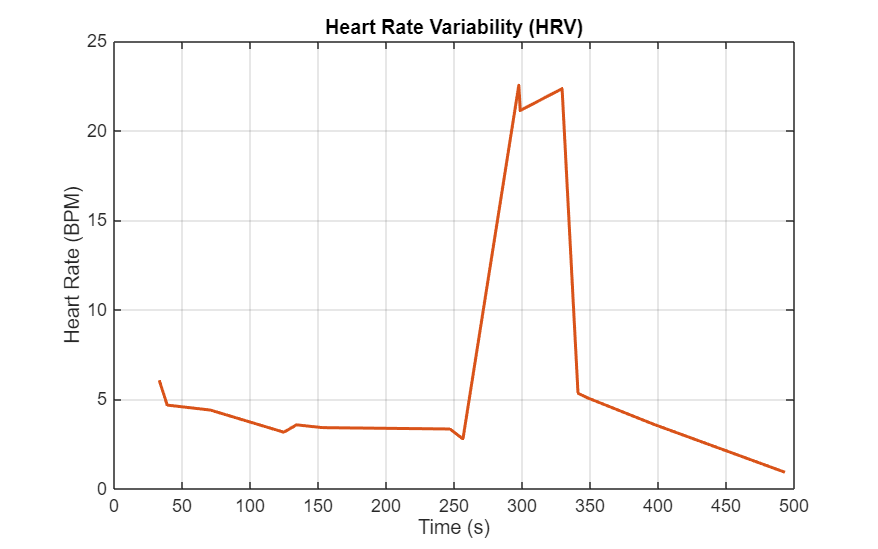

% Calculate RR intervals and heart rate
rrIntervals = diff(rpeaks) / samplingRate;
rpeakTimes = rpeaks / samplingRate;
heartRate = 60 ./ rrIntervals;
hrTime = rpeakTimes(2:end);

% Smooth the heart rate using a moving average
hrSmooth = movmean(heartRate, 3);

% Plot the Heart Rate Variablity
figure('Units','Normalized','OuterPosition',[0 0 1 1]);
plot(hrTime,hrSmooth,'Color',[0.8500 0.3250 0.0980],'LineWidth',2);
xlabel('Time (s)','FontSize',14);
ylabel('Heart Rate (BPM)','FontSize',14);
title('Heart Rate Variability (HRV)','FontSize',16);
grid on;
set(gca,'FontSize',12);